# Unidad 6 - TP08b

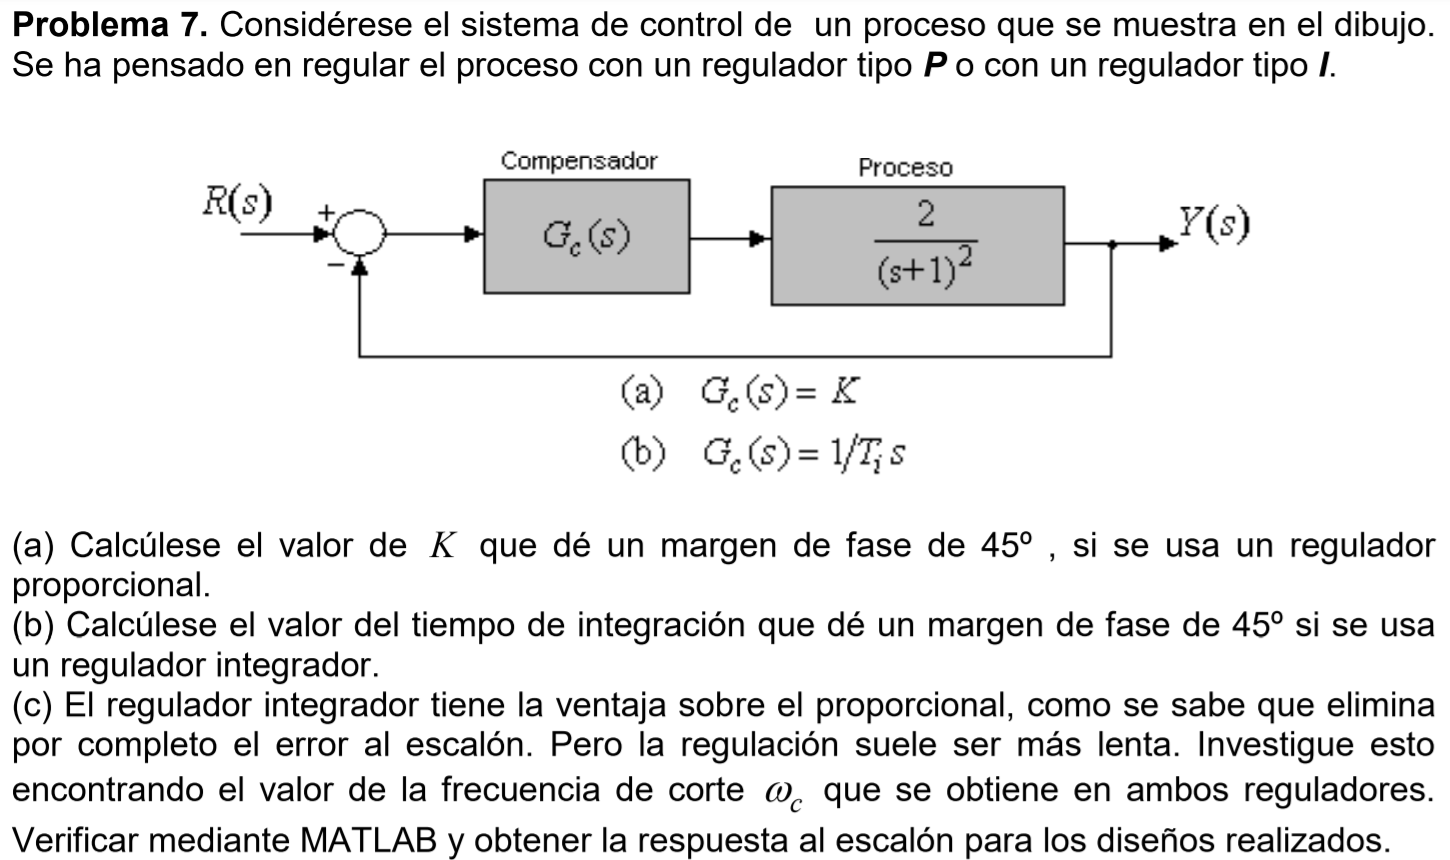

## Requisitos

- 
$$\textrm{MF}=45°$$


## Controlador Proporcional


$$G\left(s\right)=\frac{2}{{\left(s+1\right)}^2 }$$


Del diagrama de Bode obtenemos la frecuencia $w_c$ en donde cumplimos con nuestro MF. Y la ganancia que debe aportar nuestro controlador para lograr que eso suceda ${\left(k_c \right)}_{\textrm{dB}} =\left|{G\left(w_c \right)}_{\textrm{dB}} \right|\ldotp$

clear;
s = tf('s');
G = 2/(s+1)^2;
H = 1;
bode(G*H);
grid on;

Quedando entonces $w_c =2\ldotp 41\;\frac{\textrm{rad}}{s}$ y ${\left(k_c \right)}_{\textrm{dB}} =10\ldotp 7\;\textrm{dB}\ldotp$

wc = 2.41;
kc = 10 ^ (10.7/20)

## Verificación control proporcional

Gc_p = kc;
M = feedback(G,H);
M_p = feedback(Gc_p*G, H)

% Respuesta al escalón
step(M, M_p);
grid on;
legend("Sin compensar", "Controlador P");

% Bode
margin(Gc_p*G*H);
grid on;

## Análisis control Integral

Analizaremos ahora los mismos puntos del punto anterior pero con un control I.

Considerando la constante $k_I$ de nuestro controlador como unitaria hallaremos cuanta ganancia le debe aportar este controlador para poder obtener el MF requerido en la frecuencia $w_I$, es decír ${\left(k_I \right)}_{\textrm{dB}} =-{\;G\left(w_I \right)}_{\textrm{dB}}$

bode(G/s);
grid on;

Obteniendo ${\left(k_I \right)}_{\textrm{dB}}$ = -12.6 dB

ki = 10^(-12.6/20)

## Verificación controlador Integral

Gc_i = ki/s; 
M_i = feedback(Gc_i * G, H)

%Respuesta al escalón
step(M, M_p, M_i);
grid on;
legend("Sin compensar", "Controlador P", "Controlador I");

% Bode
bode(M, M_p, M_i);
grid on;
legend("Sin compensar", "Controlador P", "Controlador I");